Выбираем числа $a,t_1 ,t_2$ , что $t_1 <t_2$. 

Берём функцию g, что 


$$g\left(t\right)=\left\lbrace \begin{array}{ll}
a & t\in \left\lbrack t_1 ,t_2 \right\rbrack \\
0 & ,\textrm{else}
\end{array}\right.$$


% Задайте значения параметров a, t1 и t2
a = 3;
t1 = -2;
t2 = 4;

Теперь возьмём большой интервал времени $T$ и маленький шаг дискретизации $\textrm{dt}$

T = 20;
dt = 0.01;
% Создайте диапазон значений t
t=-T/2:dt:T/2;

Найдём зашумлённую версию сигнала как


$$u=g+b*\left(\textrm{rand}\left(\textrm{size}\left(t\right)\right)-0\ldotp 5\right)+c*\sin \left(d*t\right);$$


% зададим дополнительные коэффиценты - на рандом пока что
b = 1; 
c = 0; 
d = 0;

Построим график фильтра

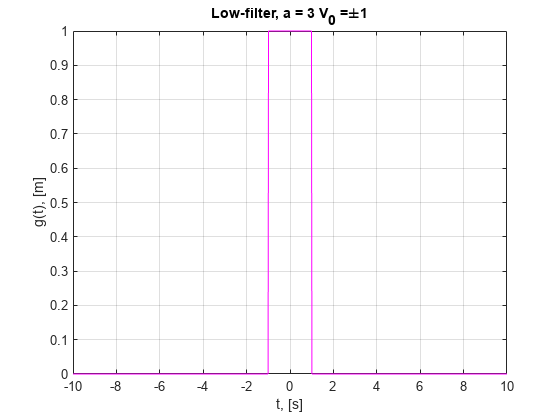

% Зададим диапазон чистки --> [-V0; V0]
V0 = T/20;
V1 = T/10;
plotFilter(1, t, V0,V1, a);

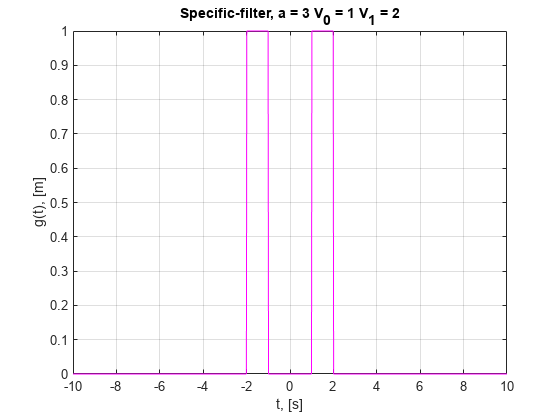

plotFilter(2, t, V0,V1, a);

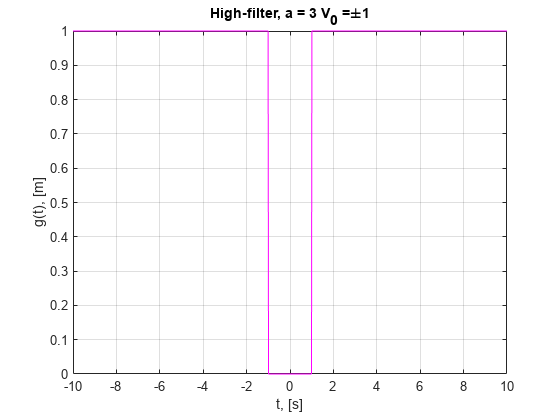

plotFilter(3, t, V0,V1, a);

Получим зашумлённый сигнал и его образ ниже

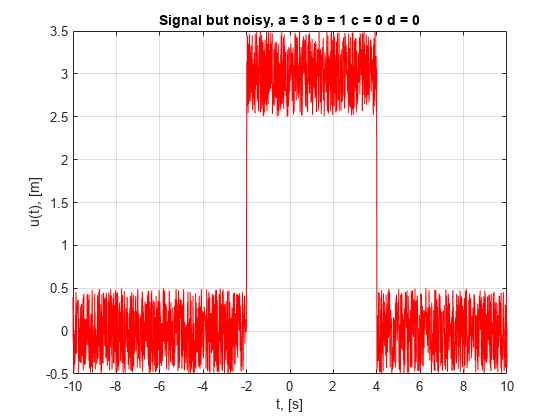

u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
U = fftshift(fft(u)); % Прямое преобразование (быстрое)
plotSignal(t, t1,t2, a,b,c,d)

Давайте ограничим область видимых частот, чтобы сделать график визуально приятнее

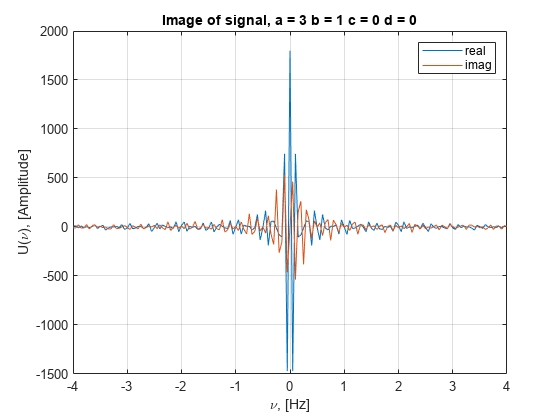

plotImage(t, t1,t2, a,b,c,d,  dt, T)

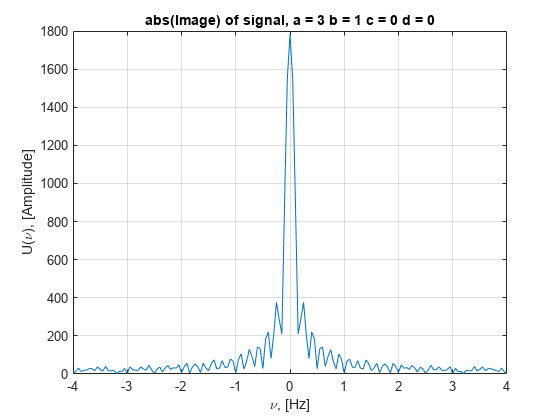

plotAbsImage(t, t1,t2, a,b,c,d,  dt, T)

## Задание 1. Жёсткие фильтры

*Общий подход к заданию таков: находим Фурье-образ сигнала ****u****, после обнуляем его значения на некоторых (выбранных вами) диапазонах частот, затем восстанавливаем сигнал с помощью обратного преобразования...*

### Убираем высокие частоты

Положите $c=0$

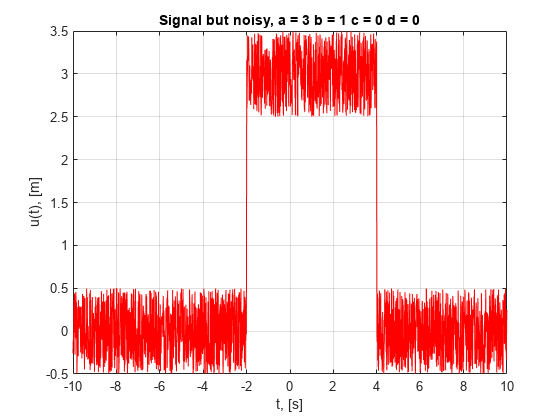

c=0; plotSignal(t, t1,t2, a,b,c ,d);

**Пусть наш сигнал начинается с нулевой секунды и длится до конца графика вправо**

Теперь найдём образ сигнала

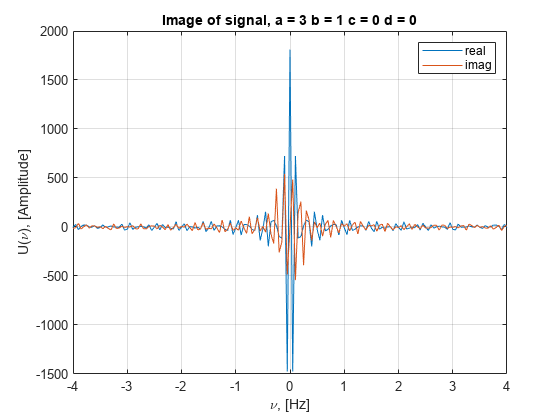

plotImage(t, t1,t2, a,b,c,d, dt, T)

Оставим следующий диапазон низких частот $\left\lbrack -\nu_0 \;;\nu_0 \right\rbrack \to \left\lbrack -3;3\;\right\rbrack \;\textrm{Hz}$ , тогда для этого составим следующий фильтр

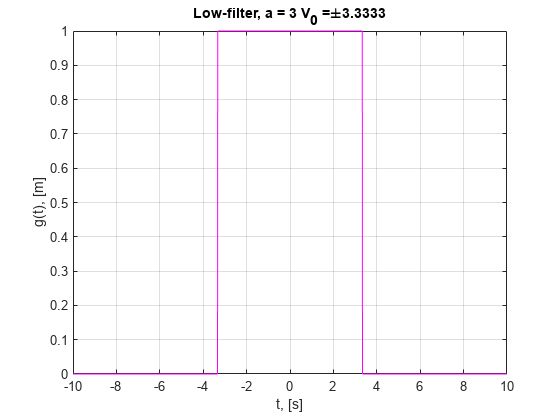

t1=-2; t2=2; V0 = T/6; plotFilter(1, t, V0,V1, a)

Тогда применим этот фильтр:

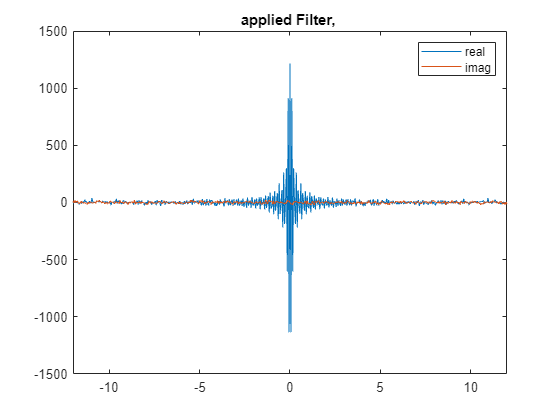

applyFilter(1, t, t1,t2, a,b,c,d, dt, T, V0, V1)

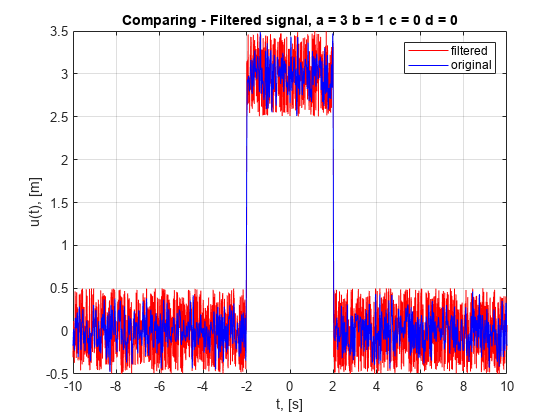

plotPure(1, t, t1,t2, a,b,c,d, V0, V1)

Проведём исследование на зависимость всего от параметра $b$ и от частоты среза $\nu_0$

$b=5$ и $\left\lbrack -1\;;1\right\rbrack$

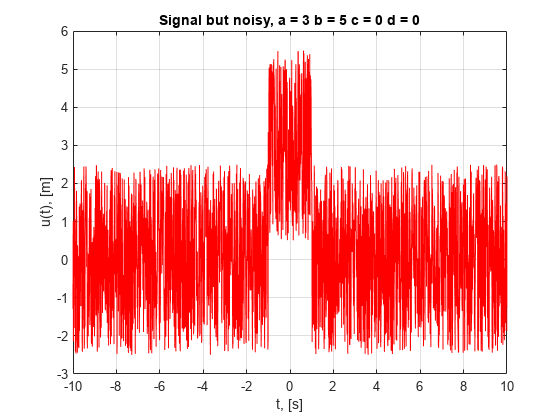

b=5; c=0; t1=-1; t2=1; V0 = T/12;
plotSignal(t, t1,t2, a,b,c,d);

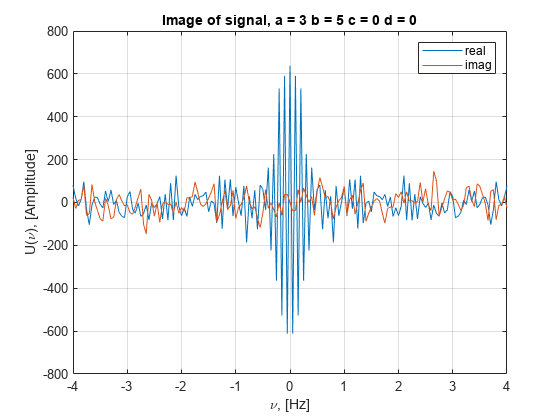

plotImage(t, t1,t2, a,b,c,d, dt, T);

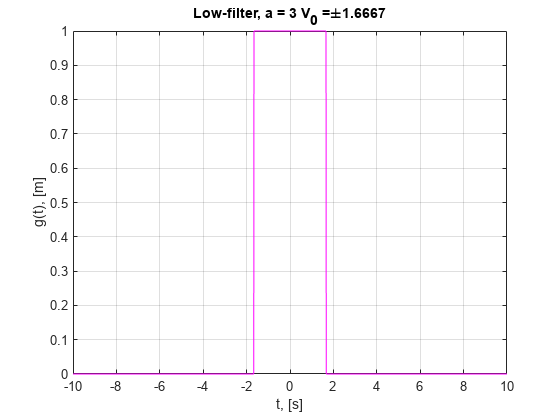

plotFilter(1, t, V0,V1, a);

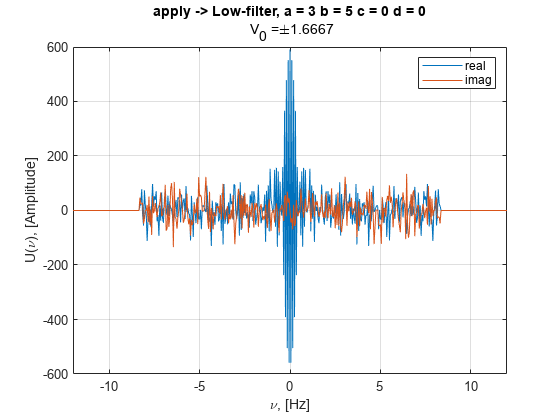

applyFilter(1, t, t1,t2, a,b,c,d, dt, T, V0, V1)

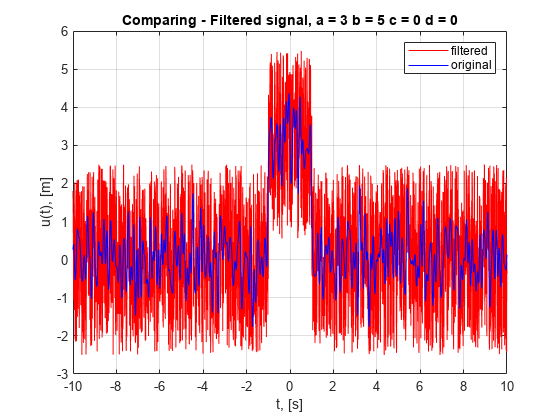

plotPure(1, t, t1,t2, a,b,c,d, V0, V1)

$b=5$ и $\left\lbrack -4\;;\;4\right\rbrack$

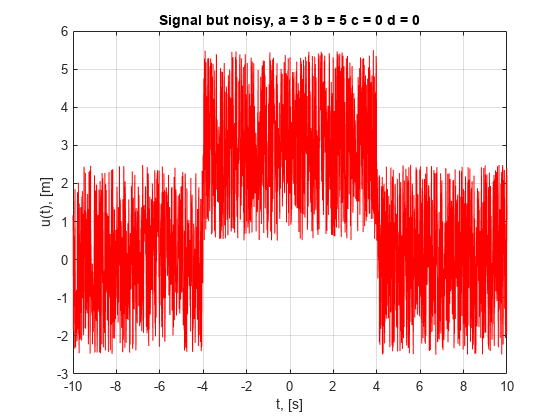

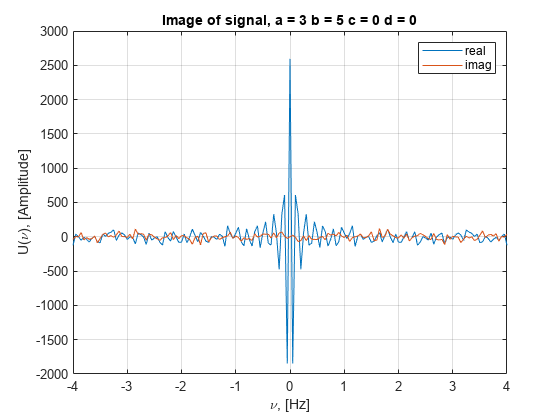

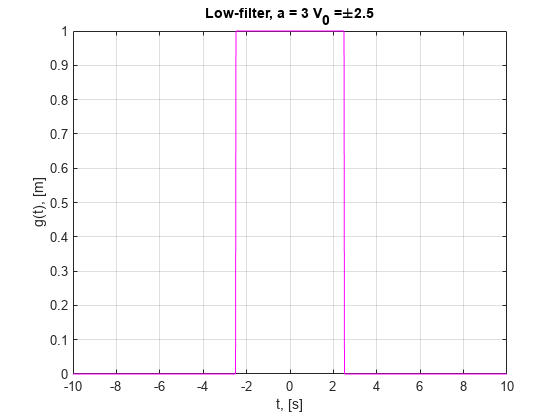

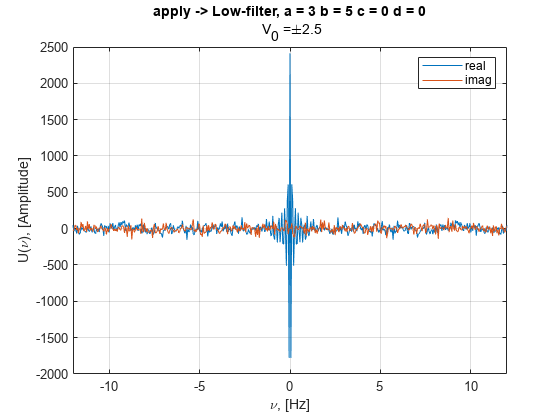

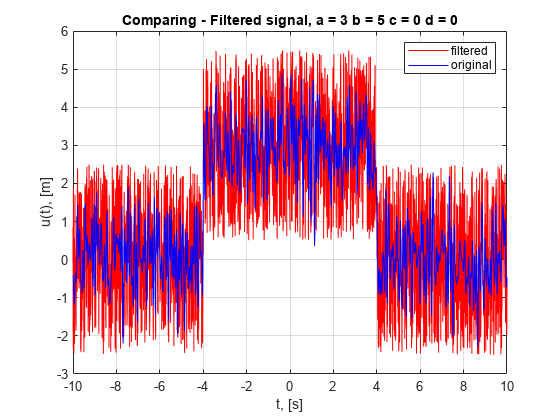

b=5; c=0; t1=-4; t2=4; V0 = T/8;
analysis(1, t, t1,t2, a,b,c,d, dt, T, V0, V1) 


$$b=2\;;\nu_0 =\left\lbrack -8\;;8\right\rbrack$$
 

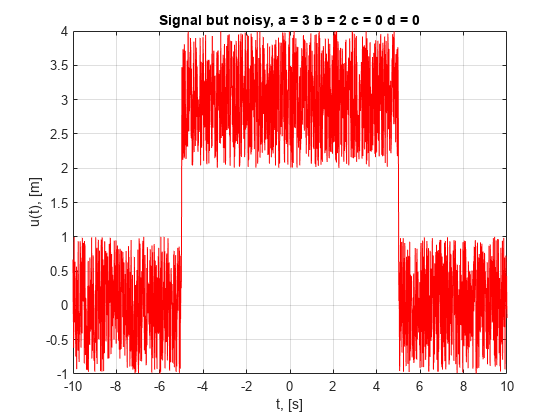

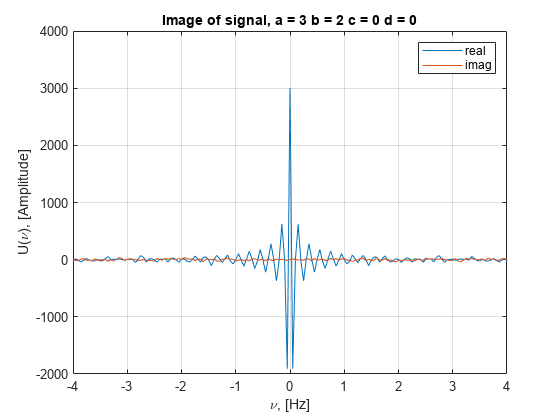

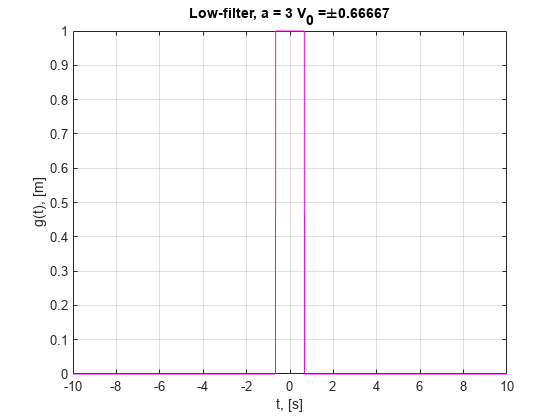

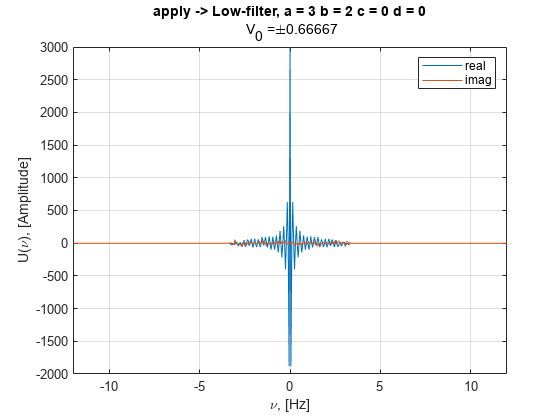

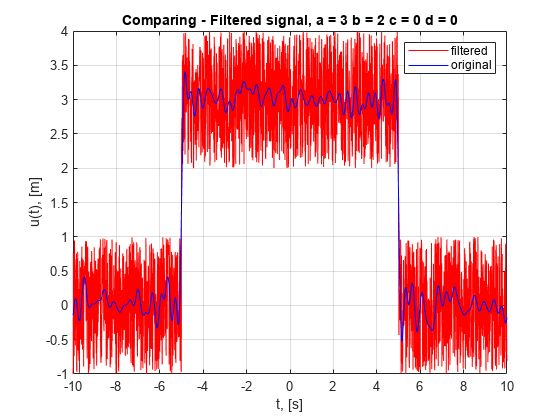

b=2; c=0; t1=-5; t2=5; V0 = T/30;
analysis(1, t, t1,t2, a,b,c,d, dt, T, V0, V1)

хе-хе

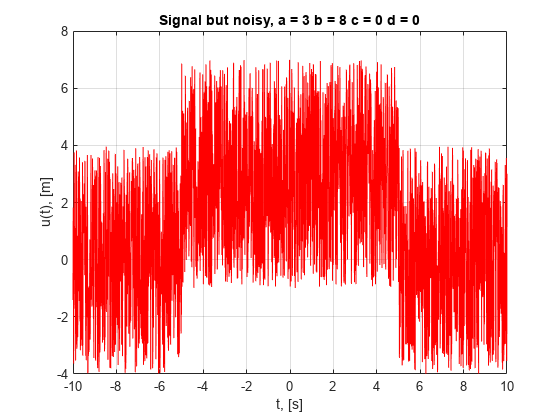

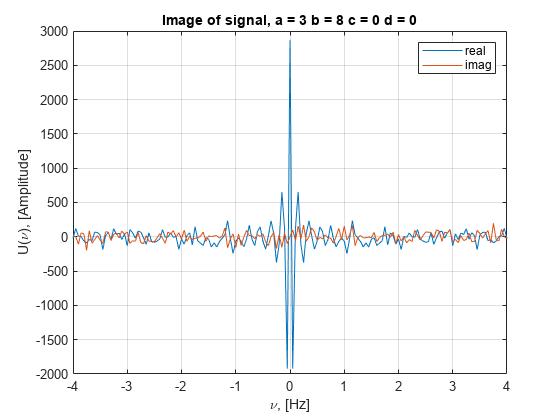

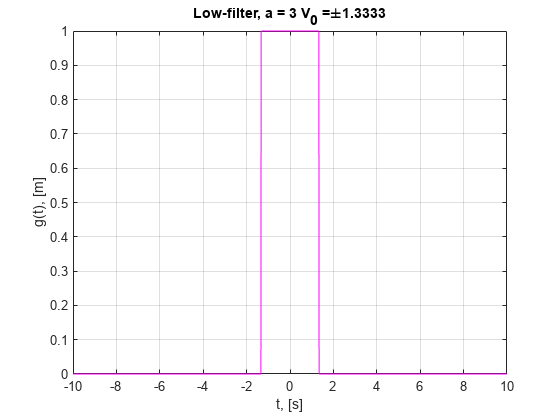

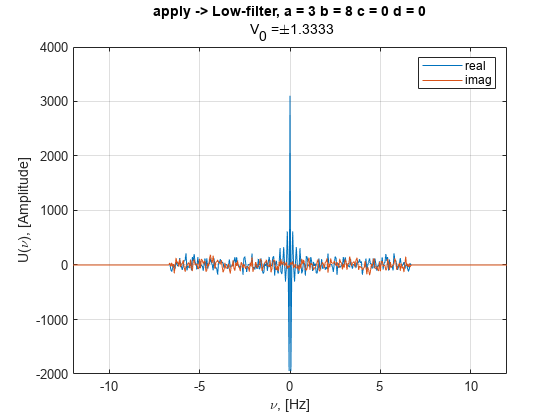

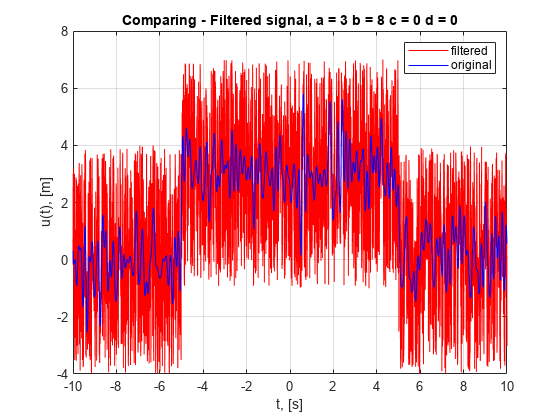

b=8; c=0; t1=-5; t2=5; V0 = T/15;
analysis(1, t, t1,t2, a,b,c,d, dt, T, V0, V1)

#### Выводы

При увеличении $b$ мы добавляем больше сбвига амплитуд в исходную синусоиду, что усложняет дальнешую фильтрацию и возвращение к исходной функции. При небольшой срезе мы теряем больше информации о функции, но взамен получаем более гладкий и "красивый" вариант, иначе же, то есть при бОльшем срезе, мы рискуем оставить шумы, которые особо не дадут нам понять что же за функция была в оригинале

### Убираем специфические частоты

**1 испытание**

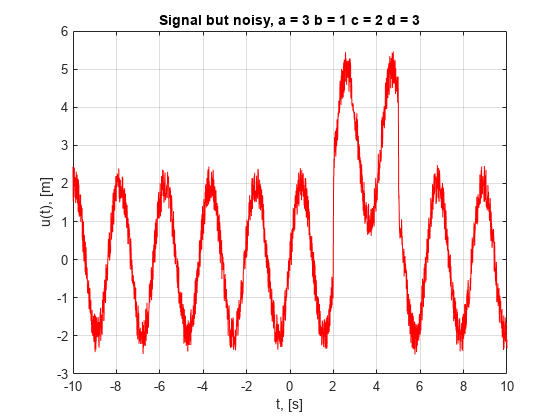

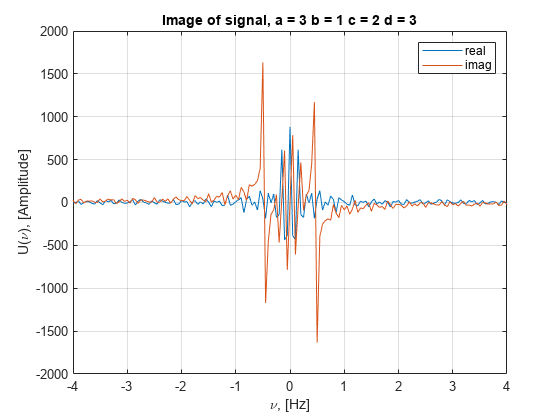

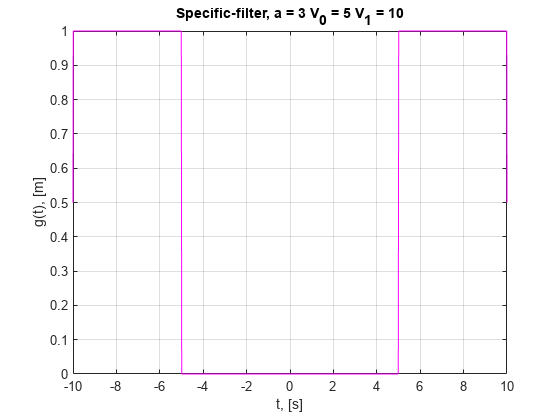

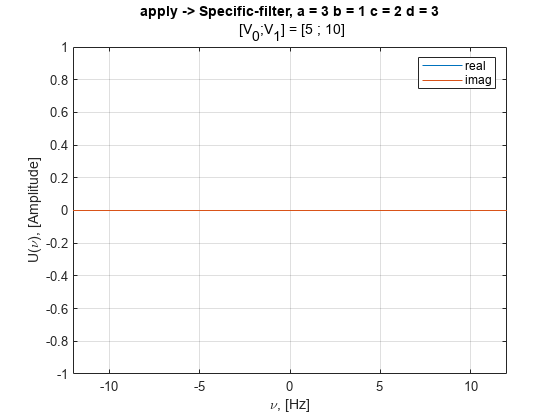

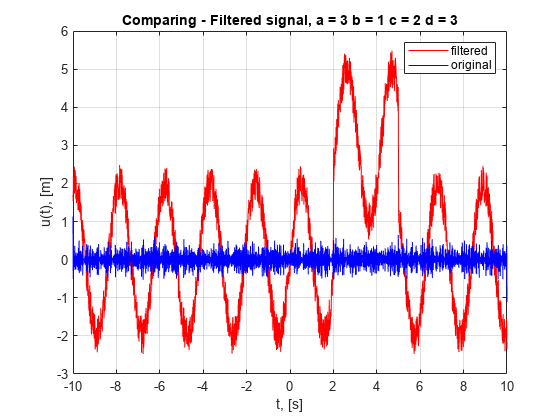

b=1;c=2;d=3; t1=2; t2=5; V0 = T/4; V1 = T/2;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

**2 испытание**

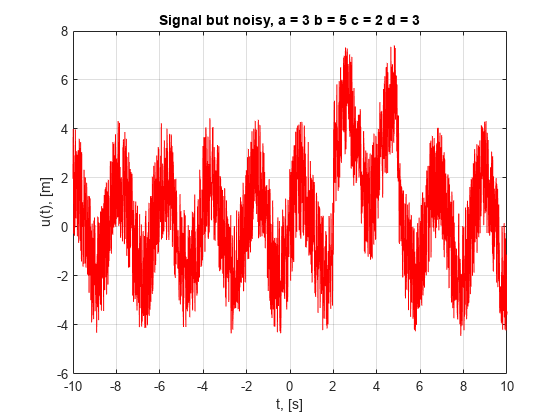

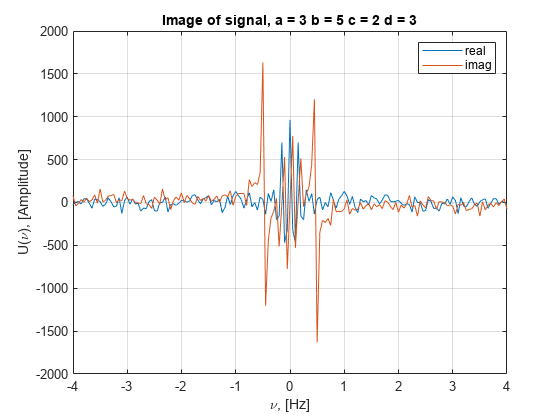

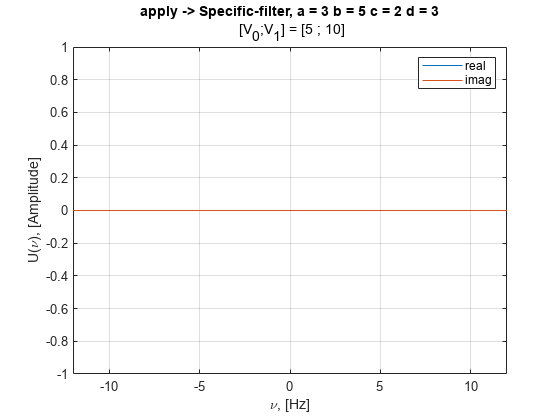

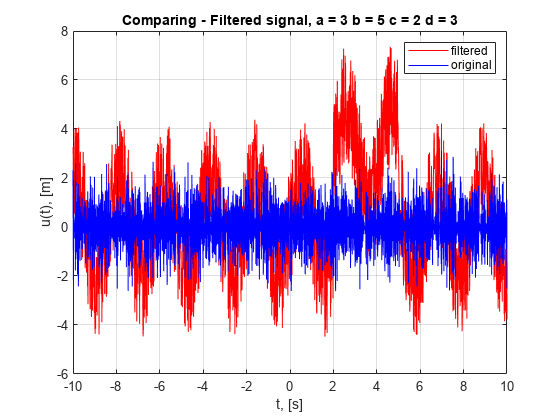

b=5;c=2;d=3; t1=2; t2=5; V0 = T/4; V1 = T/2;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

**3 испытание**

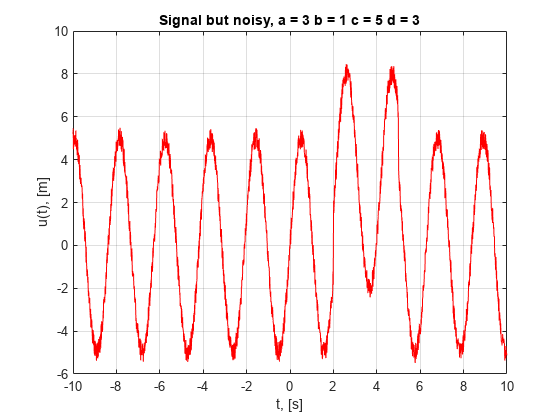

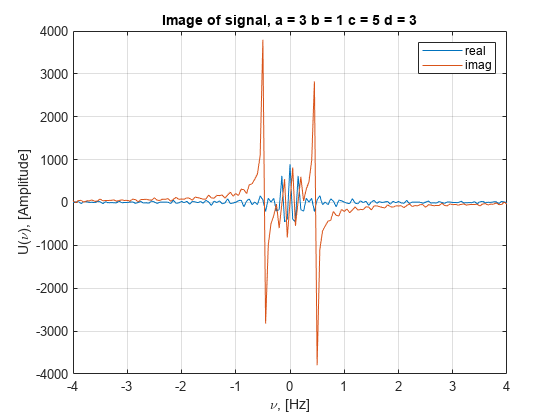

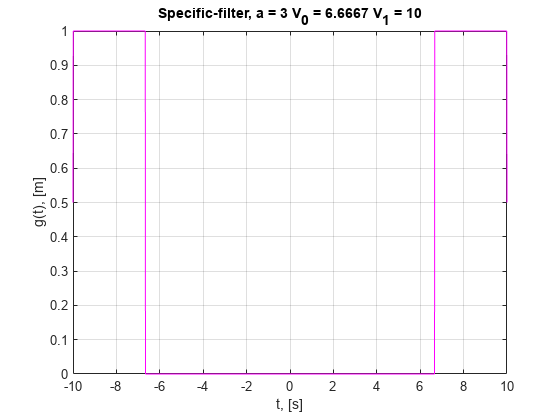

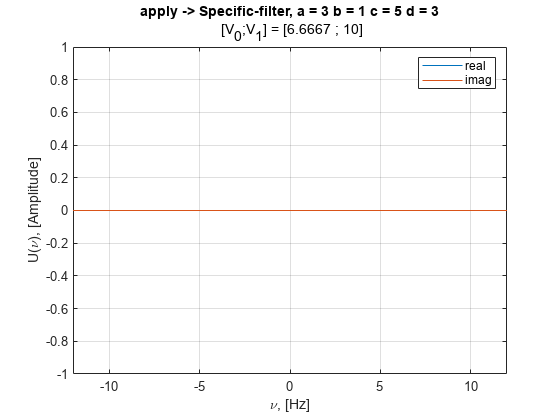

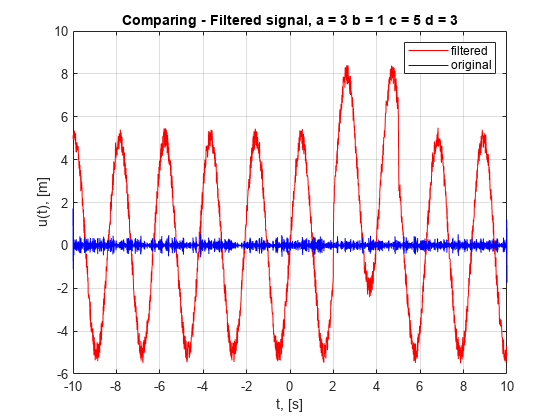

b=1;c=5;d=3; t1=2; t2=5; V0 = T/3; V1 = T/2;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

**4 испытание**

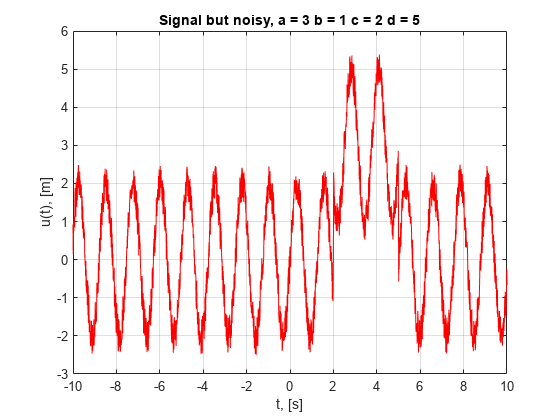

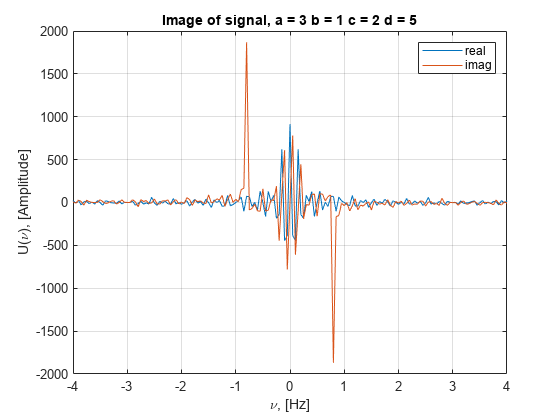

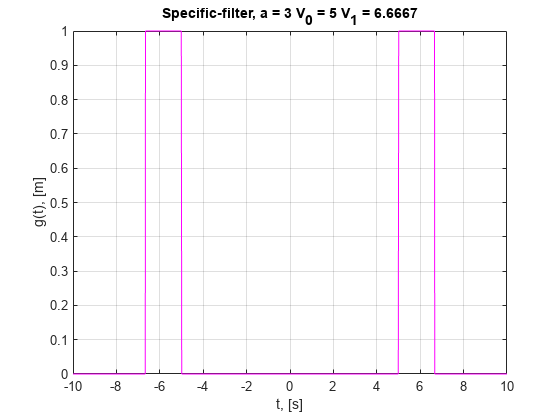

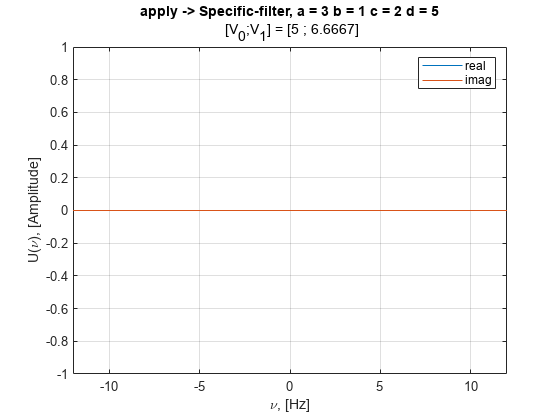

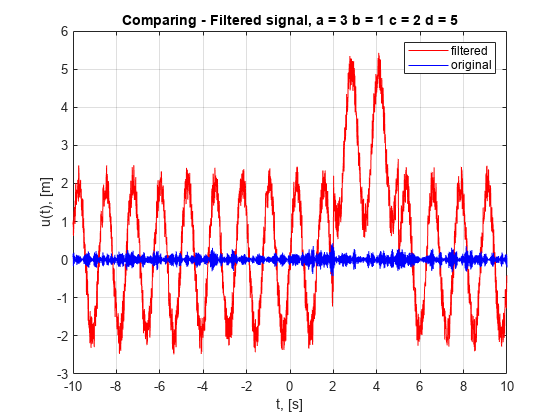

b=1;c=2;d=5; t1=2; t2=5; V0 = T/4; V1 = T/3;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

**5 испытание --> отдельный случай, b=0**

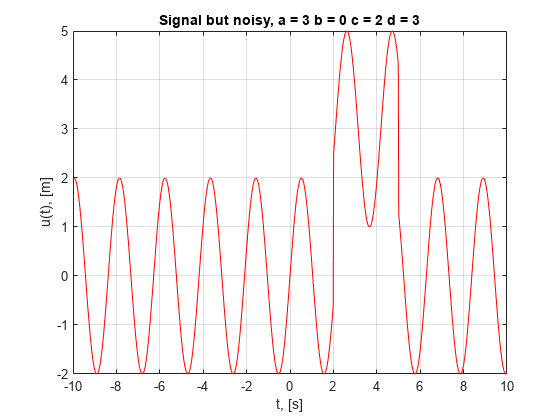

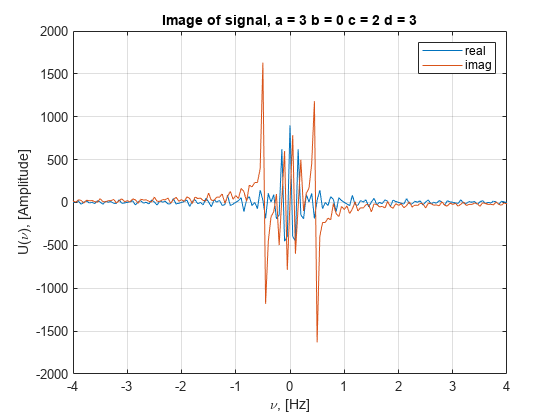

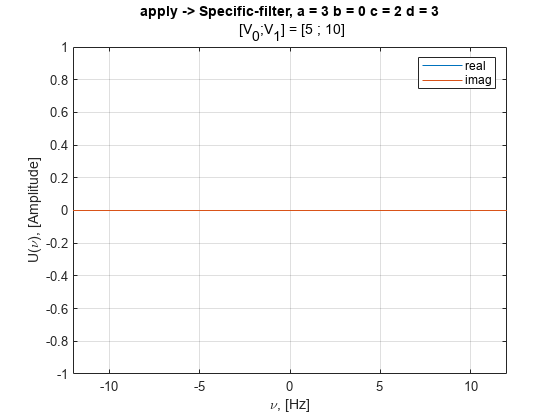

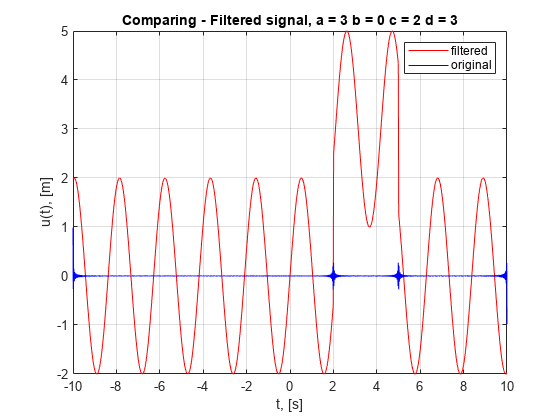

b=0;c=2;d=3; t1=2; t2=5; V0 = T/4; V1 = T/2;
analysis(2, t, t1,t2, a,b,c,d, dt, T, V0, V1)

### Убираем низкие частоты

##  Все функции, используемые в скрипте

### Первое задание

***Вспомогательная функция для помех***

function y = g(t, a, t1, t2)
    y = a * (heaviside(t - t1) - heaviside(t - t2));
end

**Фильтр высоких частот**

function y = g_inv(t, V0)
y = 1 - (heaviside(t + V0) - heaviside(t - V0));
end

**Фильтр специфических частот**

function y = g_even(t, V0, V1)
    y = (heaviside(t - V0) - heaviside(t - V1)) + (heaviside(-t - V0) - heaviside(-t - V1));
end

**Фильтр низких частот**

function y = g_odd(t, V0)
    y = (heaviside(t + V0) - heaviside(t - V0));
end

Функция для построения графика **фильтра **

function plotFilter(select, t, V0,V1, a)
    figure( randi([1 3000],1,1) )

    if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end
    plot(t, g_t, 'magenta');

    if (select == 1)
        title("Low-filter, " + "a = "+a+" V_0 =\pm"+V0)
    elseif (select == 2)
        title("Specific-filter, " + "a = "+a+" V_0 = "+V0+" V_1 = "+V1)
    else
        title("High-filter, " + "a = "+a+" V_0 =\pm"+V0)
    end

    grid on
    xlabel('t, [s]');
    ylabel('g(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "filter_a=" + a+"_V0="+V0+"_V1="+V1;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика сигнала

function plotSignal(t, t1,t2, a,b,c,d)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    plot(t, u, 'red');
    title("Signal but noisy, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика модуля образа сигнала

function plotAbsImage(t, t1,t2, a,b,c,d, dt, T)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT

    plot(v, abs(U));
    xlim([-4; 4]);
    title("abs(Image) of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "abs_image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для построения графика образа сигнала - вещественных и комплексных компонент

function plotImage(t, t1,t2, a,b,c,d, dt, T)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);

    U = fftshift(fft(u));
    
    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT

    plot(v, real(U));
    hold on
    plot(v, imag(U));
    legend('real','imag')
    xlim([-4; 4]);
    title("Image of signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "image_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для применение **фильтра** на образы сигнала - вещественное и комплексное

function applyFilter(select, t, t1,t2, a,b,c,d, dt, T, V0, V1)
    figure( randi([1 3000],1,1) )

    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end


    V = 1/dt; % Ширина диапазона частот
    dv = 1/T; % Шаг частоты 
    v = -V/2 : dv : V/2; % Набор частот для FFT
    
    plot(v, real(U).*g_t);
    hold on
    plot(v, imag(U).*g_t);
    legend('real','imag')
    xlim([-12; 12]);
    if (select == 1)
        title("apply -> Low-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    elseif (select == 2)
        title("apply -> Specific-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" [V_0;V_1] = ["+V0+" ; "+V1+"]"})
    else
        title("apply -> High-filter, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d , {" V_0 =\pm"+V0})
    end

    grid on;
    xlabel('\nu, [Hz]');
    ylabel('U(\nu), [Amplitude]');
    hold off;
    
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "applied_filter_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end

Функция для отрисовка графика "чистого" сигнала после фильтрации

function plotPure(select, t, t1,t2, a,b,c,d, V0, V1)
    figure( randi([1 3000],1,1) )
    u = g(t,a,t1,t2) + b*(rand(size(t))-0.5) + c*sin(d*t);
    U = fftshift(fft(u));
    
     if (select == 1)
        g_t = g_odd(t, V0);
    elseif (select == 2)
        g_t = g_even(t, V0, V1);
    else
        g_t = g_inv(t, V0);
    end

    pure = U.*g_t;
    u_new = ifft(ifftshift(pure)); % Обратное преобразование
    plot(t, u, 'red');
    hold on;
    plot(t, u_new, 'blue');
    title("Comparing - Filtered signal, " + "a = "+a+" b = "+b+" c = "+c+" d = "+d)
    legend('filtered', 'original')
    grid on
%     xlim([t1, t2]);
    xlabel('t, [s]');
    ylabel('u(t), [m]');
    hold off;
    
    % in one fucntion ???
    path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
    Name = "pure_signal_a=" + a+"_b="+b+"_c="+c+"_d="+d;
    fullpath = fullfile(path, Name);
    saveas(gcf, fullpath, 'png');
end


Мета-функция для быстрого анализа по первому заданию:

function analysis(select, t, t1,t2, a,b,c,d, dt, T, V0, V1)
    plotSignal(t, t1,t2, a,b,c,d);
    plotImage(t, t1,t2, a,b,c,d, dt, T);
    plotFilter(select, t, V0,V1, a);
    applyFilter(select, t, t1,t2, a,b,c,d, dt, T, V0, V1);
    plotPure(select, t, t1,t2, a,b,c,d, V0, V1);
end



###  Второе задание